              Omar  ***M***organ   202001207 

AbdulRahman  ***A***teyya    202001398

      Mohamed  ***H***atem     202001235 

     Kareem  El***O***zeiri       202000896 

## In this project, we try to simulate an OFDM signal based on WiFi standard.

Paramters that will be needed for ofdm

%n = 2^10; %number of transmitted symbols
SC = 64; %number of subcarriers
CycPref = 16; %cyclic prefix length
M = 64; %modulation scheme number
%h = [1+1j*0.53 1.3-1j*.56 1.21j*0.89 2.5+1j*-.5];   %Channel 
h = [0.8208+0.2052j,0.4104+0.1026j,0.2052+0.2052j,0.1026+0.1026j];
h = h/norm(h);

path_img = 'smaller_paddington.png';
code_rate = 1/3;
mod_type = '16-QAM';
pilots_value = [1,1,1,-1];
pilots_index = [8,22,44,58];
zeros_index = [1,28:38];
SNR = 50;
img_size = size(imread(path_img));

%getting bit stream and converting it into symbols
bitstream = img2binary(imread(path_img));


coded_bitstream = FEC_code(bitstream, code_rate);
Symbols = symbol_mapper(coded_bitstream, mod_type);
symsLen = length(Symbols);


SNR_vals = [5:5:50];
ber_zero = [];
ber_wiener = [];
for i = 1:10
tx_signal = Modulator(Symbols);
haircut_signal = ClipAndFilter(tx_signal,0.7);

%%adding noise here

fs = 1;
ricianChan= comm.RicianChannel('SampleRate',1, ...
    'PathDelays',[1 2]*1/fs, ...
    'AveragePathGains',[0,-3]*1/fs, ...
     'KFactor',1, ...
    'MaximumDopplerShift',10^-4, ...
    'ChannelFiltering',true); % Create Rician Fading Channel
  ychan=  ricianChan(haircut_signal);


noisy_sig = awgn(ychan,SNR);
%conv_sig = conv(haircut_signal,h);
conv_sig_noisy = awgn(haircut_signal,SNR_vals(i));

[signal_equalized_zero , signal_equalized_wiener] = OFDM_demodulator(CycPref,symsLen,SC,conv_sig_noisy,pilots_value,pilots_index,SNR_vals(i));

rec_signal_zeros = get_symbols(signal_equalized_zero,pilots_index,zeros_index);
rec_signal_wiener = get_symbols(signal_equalized_wiener,pilots_index,zeros_index);

rec_signal_zeros = rec_signal_zeros(:);

rec_signal_wiener = rec_signal_wiener(:);

signal_zero = symbol_demapper(rec_signal_zeros, mod_type);
signal_wiener = symbol_demapper(rec_signal_wiener, mod_type);

rec_bits_zero = FEC_decode(signal_zero, code_rate);
rec_bits_wiener = FEC_decode(signal_wiener, code_rate);
BER_zero = sum(rec_bits_zero == bitstream')/length(bitstream);
BER_wiener = sum(rec_bits_wiener == bitstream')/length(bitstream);
ber_zero = [ber_zero, BER_zero];
ber_wiener = [ber_wiener, BER_wiener];

end


rec_imag_zero = binary2img(rec_bits_zero, img_size);

rec_imag_wiener = binary2img(rec_bits_wiener, img_size);

Comparison between the BER performance of the ZF equalizer, and the Weiner equalizer for BPSK modulation, and 1/3 code rate

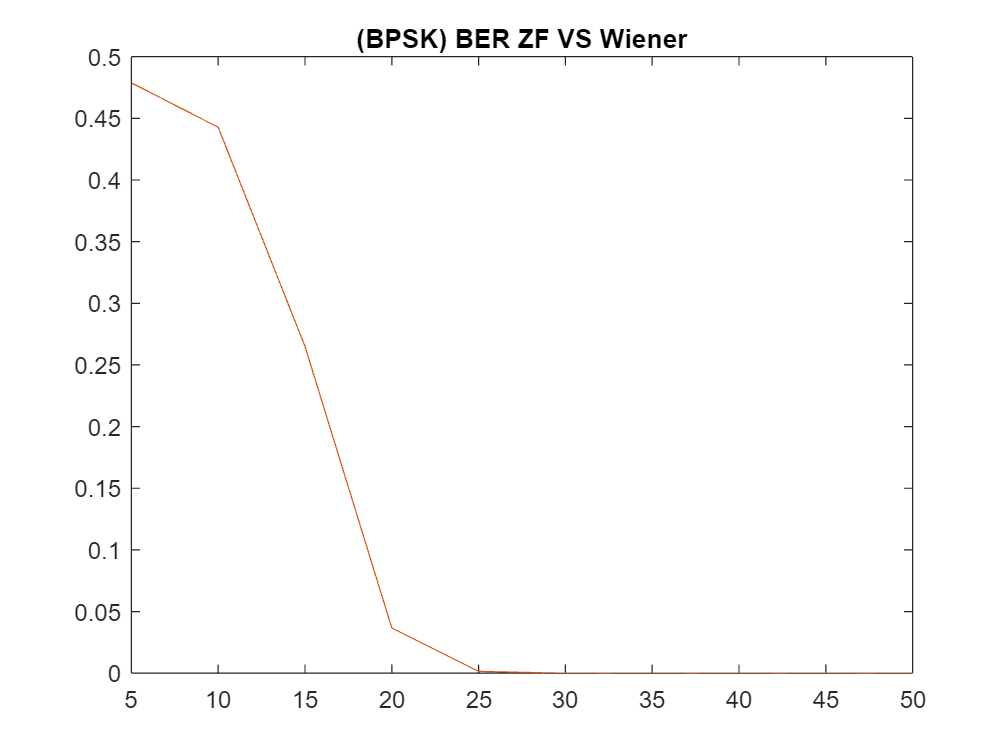

figure
plot(SNR_vals,1-ber_zero)
hold on
plot(SNR_vals,1-ber_wiener)
title("(BPSK) BER ZF VS Wiener")

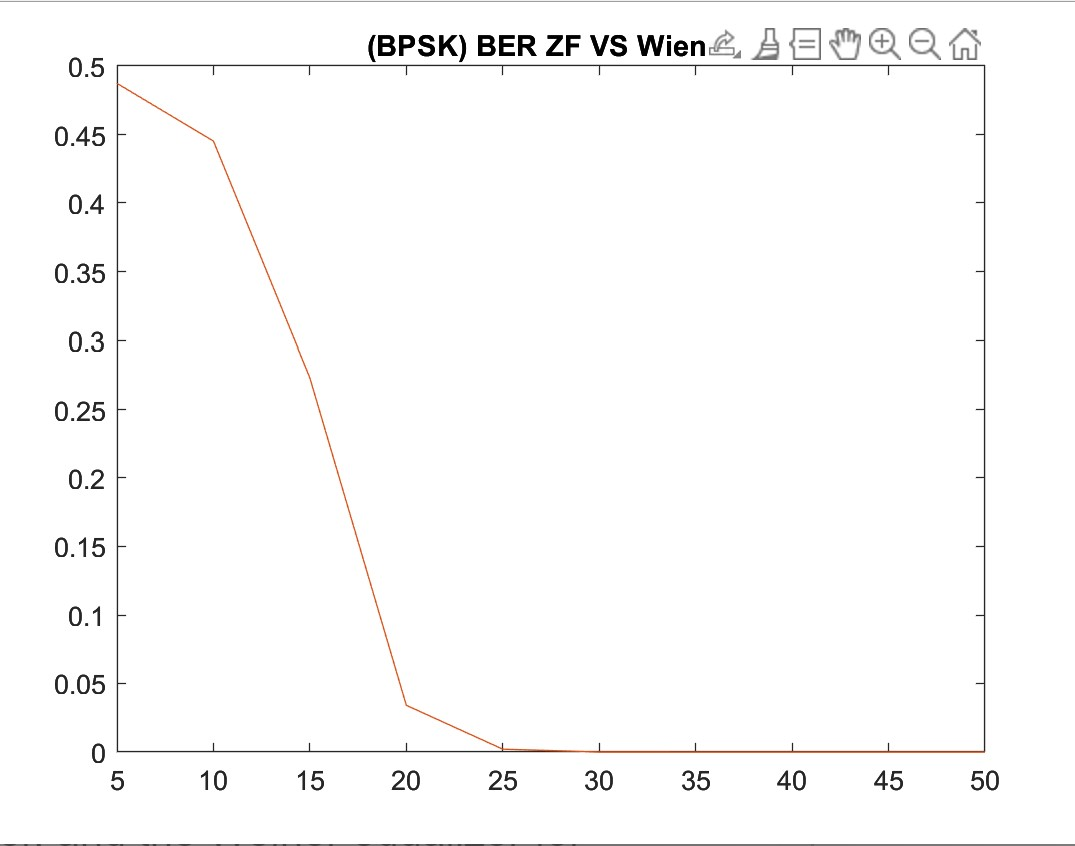

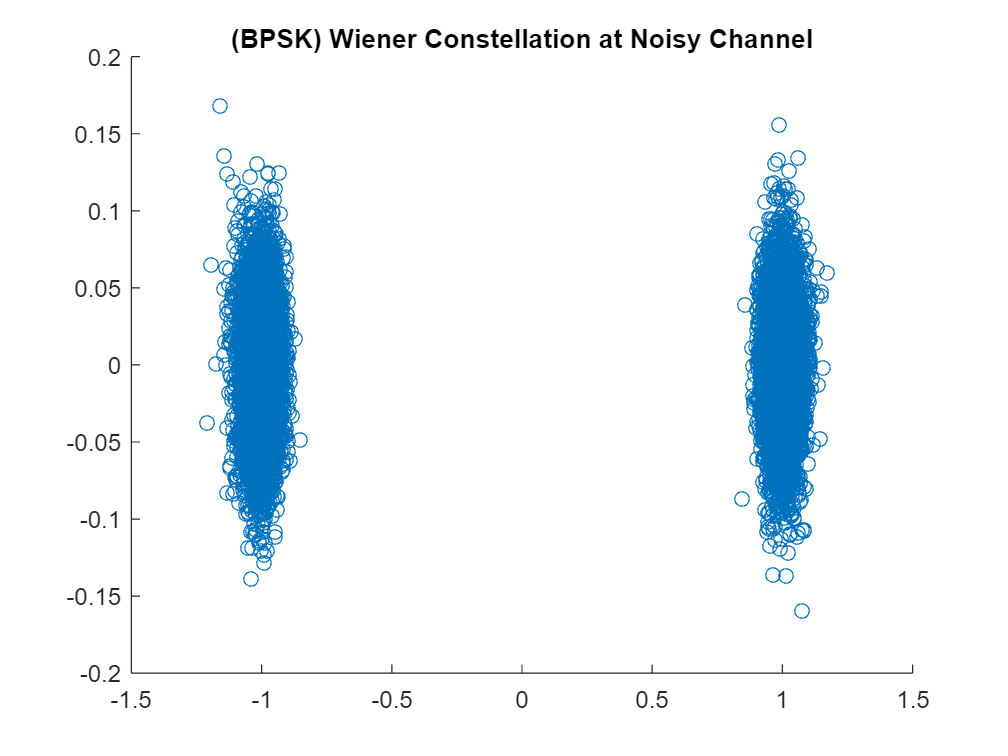

figure
scatter(real(rec_signal_wiener),imag(rec_signal_wiener))
title("(BPSK) Wiener Constellation at Noisy Channel")

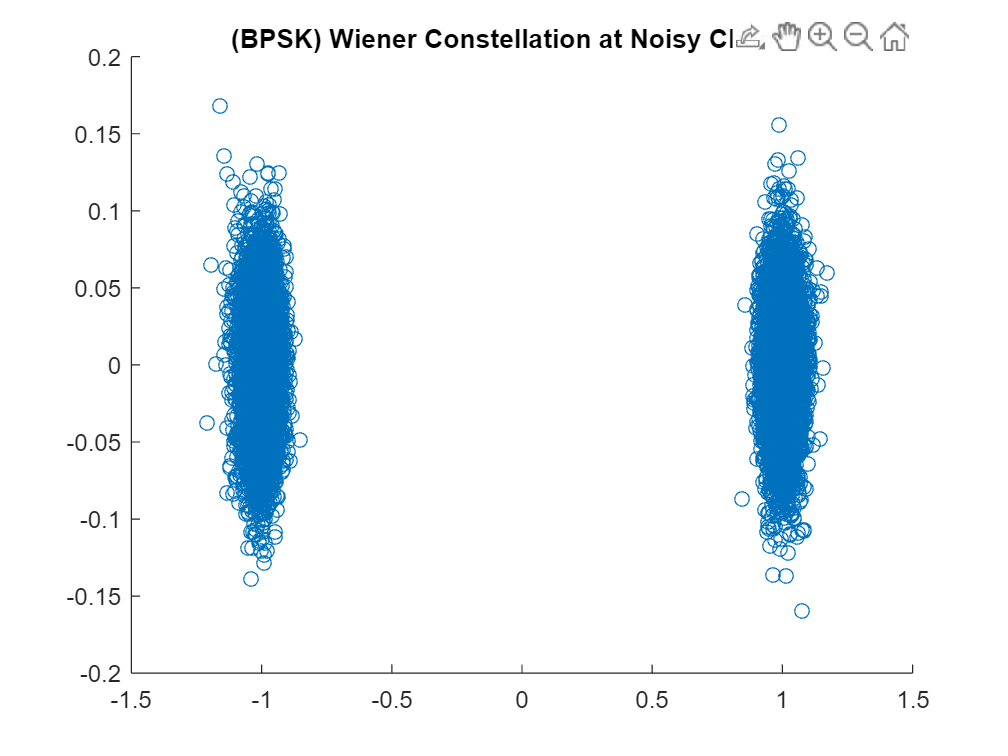

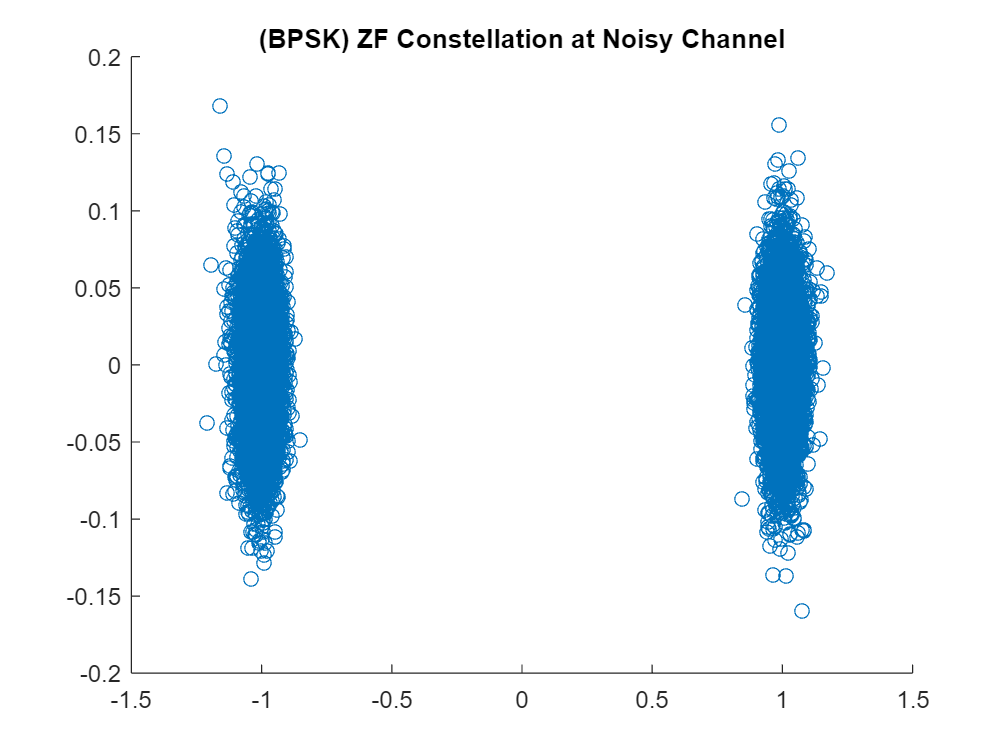

figure
scatter(real(rec_signal_zeros),imag(rec_signal_zeros))
title("(BPSK) ZF Constellation at Noisy Channel")

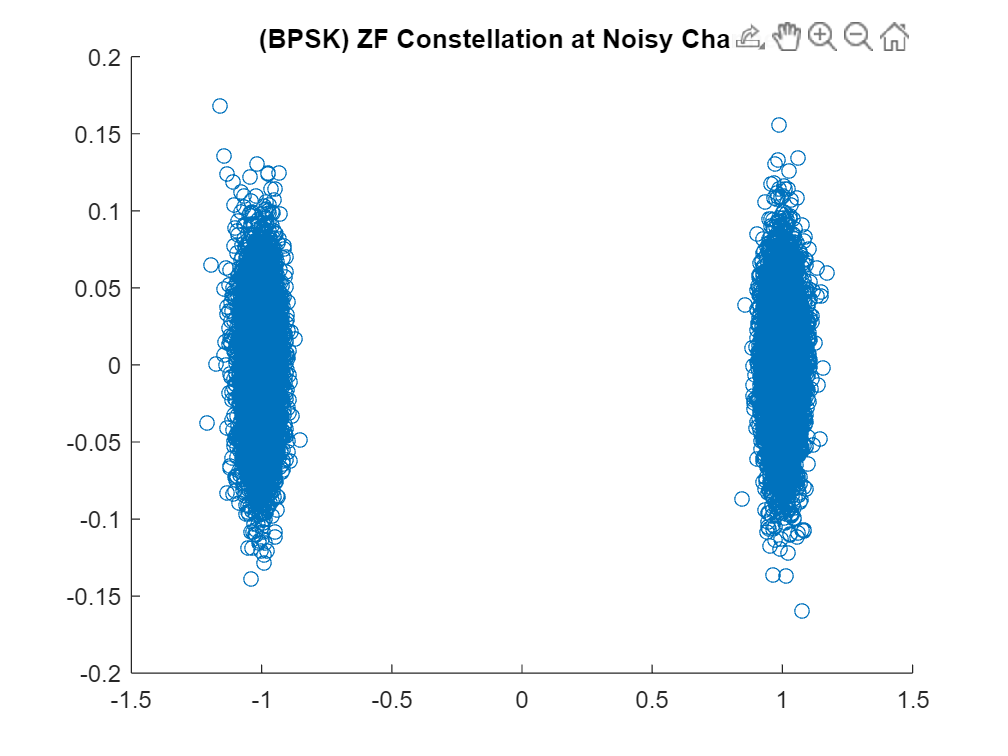

Comparison between the BER performance of the ZF equalizer, and the Weiner equalizer for QAM modulation, and 1/3 code rate

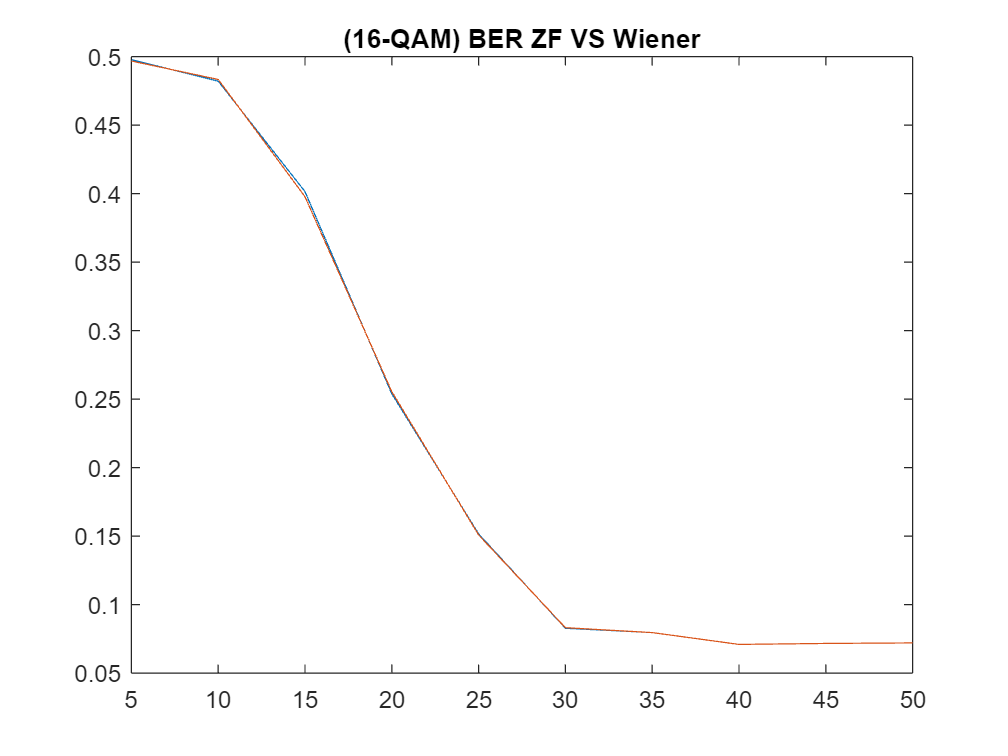

figure
plot(SNR_vals,1-ber_zero)
hold on
plot(SNR_vals,1-ber_wiener)
title("(16-QAM) BER ZF VS Wiener")

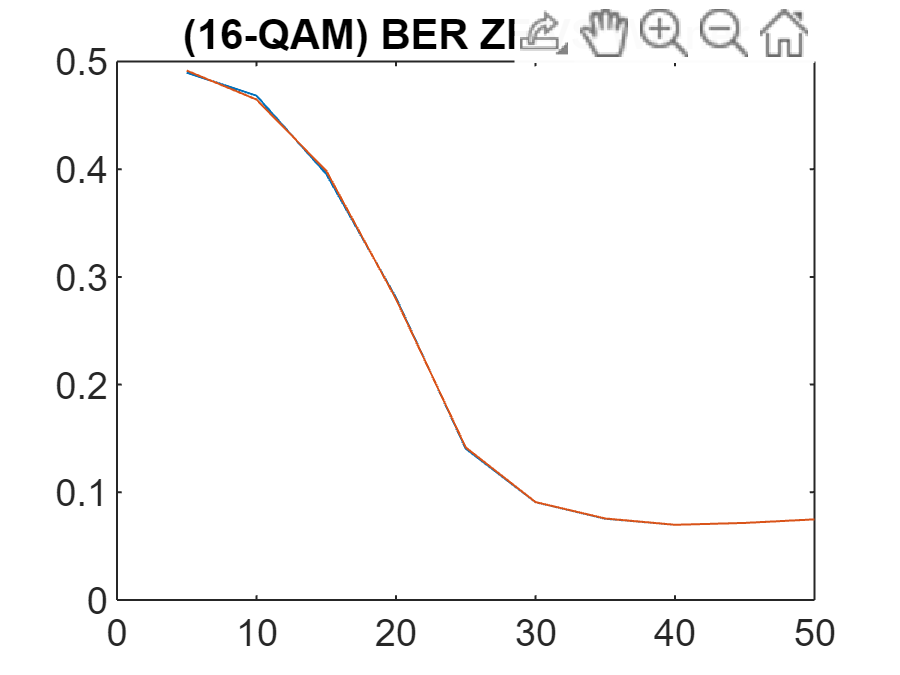

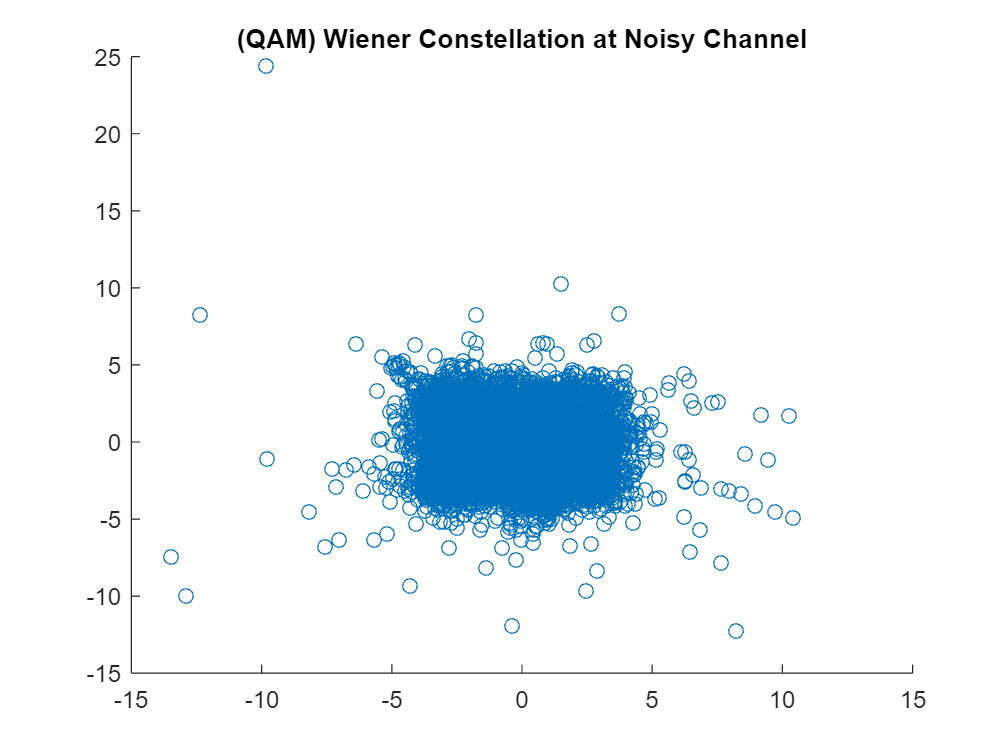

figure
scatter(real(rec_signal_wiener),imag(rec_signal_wiener))
title("(QAM) Wiener Constellation at Noisy Channel")

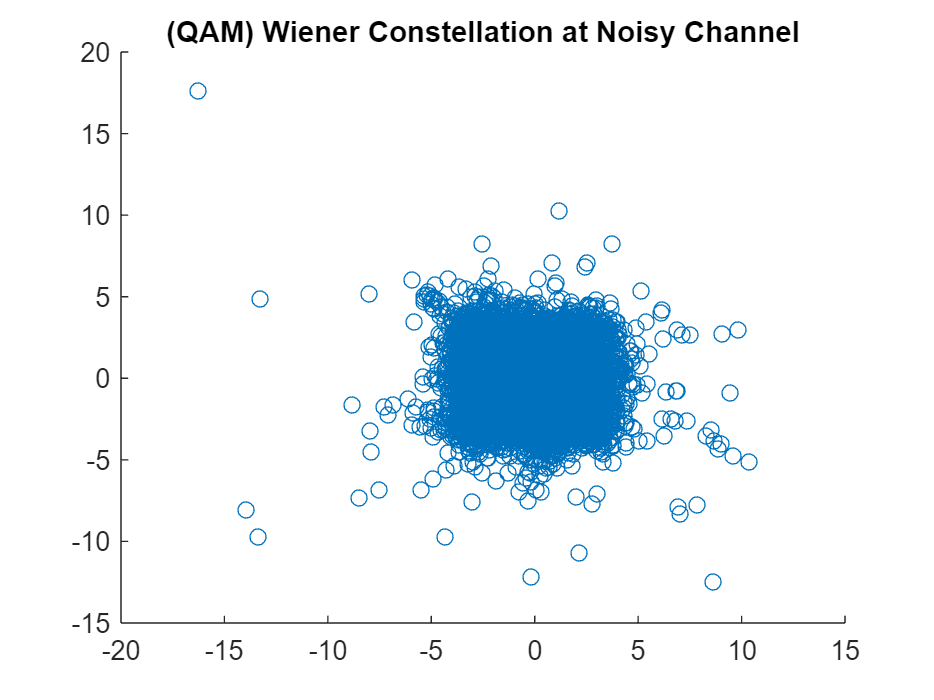

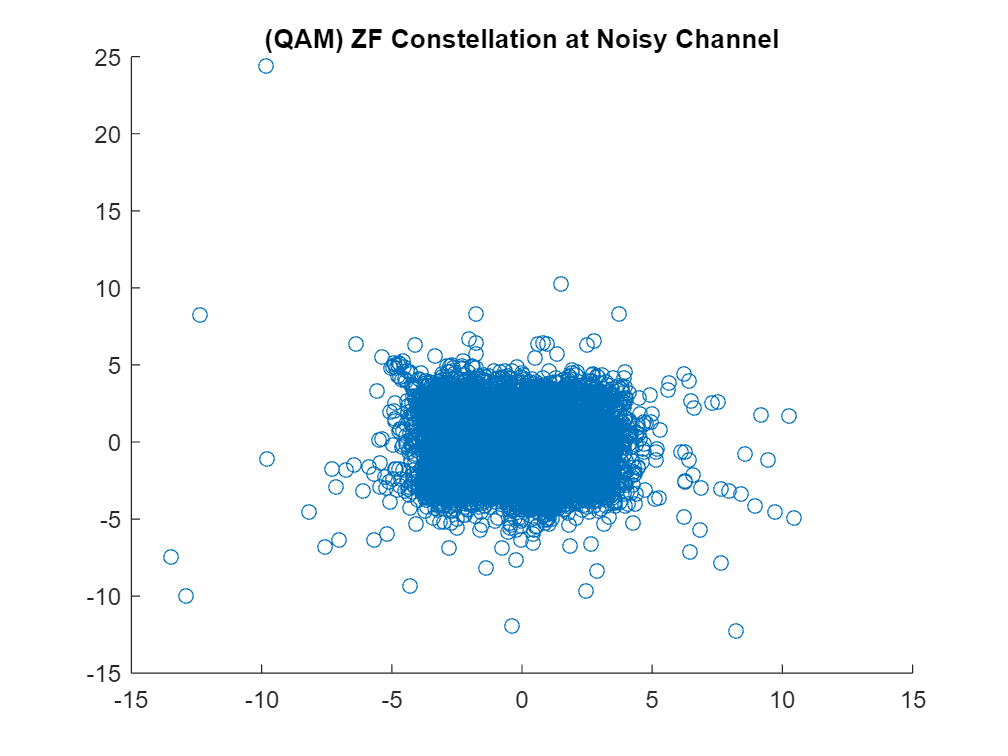

figure
scatter(real(rec_signal_zeros),imag(rec_signal_zeros))
title("(QAM) ZF Constellation at Noisy Channel")